# Machine Learning for Regression: Part 1

*                A light introduction*

**Suggested Prework**

[MATLAB Onramp](https://www.mathworks.com/learn/tutorials/matlab-onramp.html) – a free two-hour introductory tutorial to learn the essentials of MATLAB.

## What is Machine Learning?

Machine Learning refers to a set of models and algorithms that automatically **learn** information from data. It can be seen as a data-driven approach to approximate a function if the actual function is unknown. Such models are used for *clustering*—grouping data and finding hidden patterns, *classification*—assigning to known discrete categories, and *regression*—predicting continuous-valued responses.

***Task:**** Use the drop-down control to view an example of each of regression, classification, and clustering problems.*

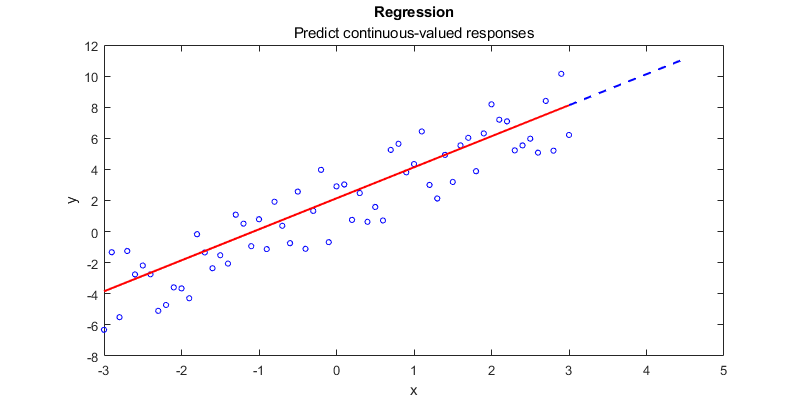

showRegression; 

Broadly, there are two types of machine learning algorithms—supervised and unsupervised. Supervised algorithms need labeled training data. The algorithm learns a relationship based on the labeled data and applies it to new unseen data. Supervised algorithms are used for classification and regression. Unsupervised algorithms, on the other hand, do not need labeled data and are used for clustering.

***Task:**** Watch *[*this video*](https://www.mathworks.com/videos/introduction-to-machine-learning-part-1-machine-learning-fundamentals-1542879625034.html)* for a brief introduction to machine learning.*

The high-level workflow for machine learning is similar to a general data analysis workflow. Here is an overview of the steps involved:

In practice, you will iterate several times between the preprocessing, feature engineering, and model development stages before deploying your final model. This module focuses on using machine learning to formulate and solve regression problems.

## 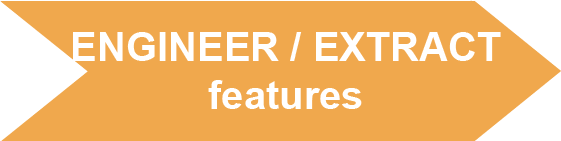Feature Engineering

To find patterns and predict discrete-valued or continuous-valued variables using data, a machine learning model relies on certain characteristics or distinguishing properties in the data. These characteristics are called features or predictors. In other words, features provide a meaningful representation of the problem to your model. For example, consider the problem of determing the selling price of a used car. The make and model, age and mileage are some of the most important predictors of the car's value. You may also consider additional characteristics like the location, exterior color, and quality ratings among others. However, the specific day or month of registration will probably have no bearing on the new selling price.

A crucial step in learning is to identify good features and extract them from the raw data. This stage is called *feature engineering*. It relies heavily on domain expertise or some prior knowledge about the dataset. A machine learning algorithm typically takes in features in the form of *feature vectors*­­­—numeric columns (or rows) for every data observation or sample. Converting raw data into useful feature vectors is called *feature extraction*.

When identifying features and extracting feature vectors, your goal is to eliminate redundancy and retain the information that best helps a machine learning model recognize meaningful patterns that will solve the problem. This is often an iterative and experimentative process. Well-formulated features can help reduce the complexity of the model required for learning.

While most practical machine learning problems will involve multiple features, you will now explore a few simple examples of 1-D data and engineer a single feature. 

***Task:**** Click the ****Test feature**** button to run this section. Your goal is to fit a simple linear regression model using the engineered feature *`x1`*.*

rng(42);                        % Set random number generator seed for reproducibility.
x = rand(21,1);                 % Generate x for sample data.
y = 0.5 + sin(2*pi*x)*0.5 + 0.21*rand(size(x));

% Create a feature vector by transforming the original data.
x1 = x;
 

testFeature(x,y,x1);

  **Try**

- *Inspect and assess the four plots above.*

- *Use the drop-down control to select an appropriate feature vector *`x1`* for each data sample *`y`*. To do this, inspect the raw data plot and try to identify a good feature transformation to fit a linear model. A good selection will result in a good linear fit (bottom right plot) in the feature space.*

- *Repeat step 2 for data samples 2, 3, and 4 (in that order) by selecting from the drop-down control for *`y`*. *

 **Reflect**

For such simple datasets, you can visually inspect the data and analytically identify/engineer a good "feature" to fit a linear regression model to the transformed data. 

- Was it necessary to design a feature in the above examples and then apply a linear regression model in the feature space (`x1`)? Could you fit a model to the raw data instead?

- What is an advantage or a disadvantage of fitting a model in the feature space? (**Hint: **Think in terms of the model complexity and making predictions for new raw observations)

- What challenges do you anticipate in designing features for real-world datasets containing speech signals, images or videos, text, or other sensor signals?

## 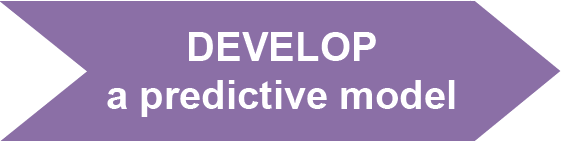Some Machine Learning Models

A few standard regression models include:

- Linear Regression

- Stepwise Linear Regression

- Regression Tree

- Ensemble of Trees

### Linear Regression

In statistics, regression is a group of techniques for estimating the relationship between a dependent variable and one or more independent variables. This notion of independent variables is closely linked to that of features or predictors in machine learning. The dependent variable, on the other hand, is also called the response variable. In machine learning terminology, a regression model describes the relationship between predictors and a continuous-valued response. A *linear* regression model is linear in the model coefficients, and a *multiple* linear regression model describes the relationship between numerous predictors and one response variable.

A multiple linear regression model is

                    $y_i =\beta_o +\beta_1 X_{\textrm{i1}} +\beta_2 X_{\textrm{i2}} +\beta_3 X_{\textrm{i3}} +\ldotp \ldotp \ldotp \beta_p X_{\textrm{ip}} +\varepsilon_i$           $i=1,2,\ldotp \ldotp \ldotp n$,

where

- $y_i$ is the $i$th response

- $\beta_k$ is the $k$th coefficient and $\beta_0$ is the constant term

- $X_{\textrm{ij}}$ is the $i$th observation on the $j$th predictor variable, $j=1,2,\ldotp \ldotp \ldotp p$

- $\varepsilon_i$ is the $i$th noise term or random error

***Task:**** Learn the fundamentals of linear and nonlinear regression in *[*Regression Basics*](https://www.mathworks.com/academia/courseware/regression-basics.html)*.*

### **Stepwise Linear Regression**

This model systematically adds or removes terms from a linear regression model one step at a time, based on a specified criterion. The technique essentially incorporates feature selection with fitting a linear regression model. The terms (and the associated predictors) that are not useful in explaining the response variable are eliminated in the process.

***Task: ****Click the ****Fit linear regression model**** button to apply stepwise linear regression. Then, follow the subsequent instructions.*

*a. ****Task*****:** Select the number of predictors to generate a dataset. For the first run, use 6 predictors.

numPredictors = 6; % Number of predictors to include in the sample data
[X,y] = generateData(numPredictors);       % Generate some random data samples to perform regression

*b. ****Task*****: **Check the size of the generated variables `X` and `y`. `X` contains the observations along its rows and predictors along its columns (1 to `numPredictors`). `y` has the response for each observation.

whos X y                                   % Display the size of X and y

First, fit a constant linear regression model to create a starting model for stepwise regression. 

*c. ****Task*****:** Observe the resulting model in the output below.

startingMdl = fitlm(X,y,"constant")

Next, add or remove terms to improve the starting model in steps. Set the final model to be a linear regression model.

*d. ****Task*****:** Observe the output to see which terms are added or removed.

for N = 1:20
    updatedMdl = step(startingMdl,"Upper","linear");
    startingMdl = updatedMdl;
end

*e. ****Task*****:** View the final linear regression model. Specifically, note which terms or predictors are included in the final model.

disp(updatedMdl)

 ***Try***

- *Observe and analyze the displayed outputs as instructed above.The displayed models are specified without the use of any coefficients. The notation shows the response variable to the left of the tilde sign (*`~)`* and the predictor terms to the right. The addition of 1 refers to the intercept term. Read the documentation to learn more about *[*Wilkinson notation*](https://www.mathworks.com/help/releases/R2021a/stats/wilkinson-notation.html)*.*

- *Change the starting model type from *`"constant"`* to *`"linear"`* or *`"quadratic"`* by using the drop-down control and then rerun the section. Observe the final terms included in the model in each case.*

- *Increase or decrease the number of predictors in the generated dataset using the slider for *`numPredictors`* and run the section. For the different initial numbers of predictors, select different starting model types. In each case, note the complexity (number of terms) of the final model.*

 **Reflect**

- When or why would you choose to start with a constant model as opposed to a quadratic model?

### Regression Tree

Decision trees are supervised models that are good at capturing complex nonlinear relationships. They have a sequential hierarchical structure that resembles a tree with multiple branches, nodes, and leaves. You can interpret this structure as several nested if-else conditions used for making a decision.

                                        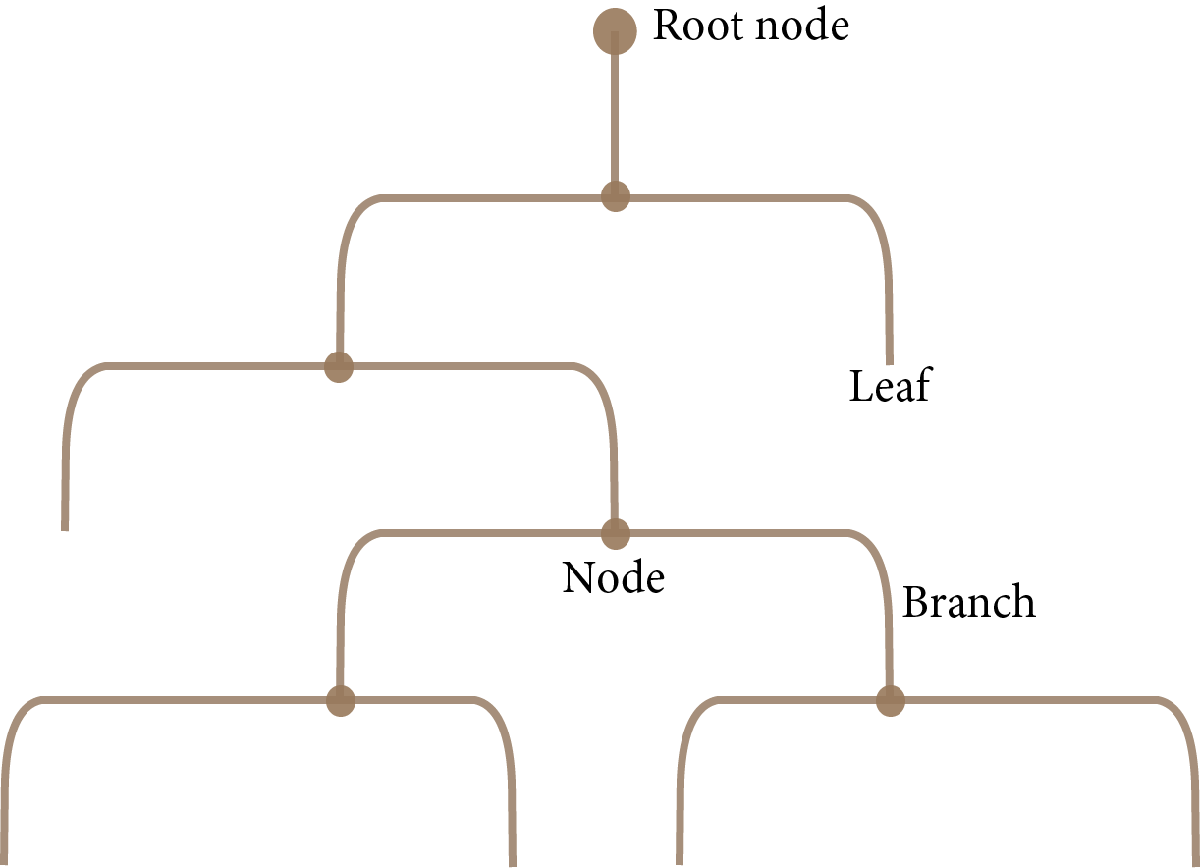

Decision trees are used for both classification and regression. When used for regression, we call them *regression trees*. Generally, a regression tree uses some rules to split the training features into subsets of those features. For sequential numerical data, the model essentially sets thresholds based on specific patterns in the training data. The regression tree structure depends on multiple split criteria, for example, the number of nodes and leaves, the number of training samples per leaf, and others.

***Task:**** Click ****Fit regression tree**** to view an example of a regression tree to model the hourly electricity load in a day.*

load loadMayDay.mat x y
numSplits =2;
 

showRegressionTree(x,y,numSplits);

  ***Try***

- *Find the actual y-value for x = 0 and x = 12 in the energy load curve. (****Hint:**** Click inside the plot and move your mouse pointer over the blue circles to find the correponding x and y values).*

- *Traverse the regression tree to obtain predictions for x = 0 and x = 12.*

- *Increase the maximum number of splits *`numTreeSplits` to `10` and repeat the previous step.

- *Draw the corresponding regression tree on paper. For example, here is a r*egression tree corresponding to two splits:

                                       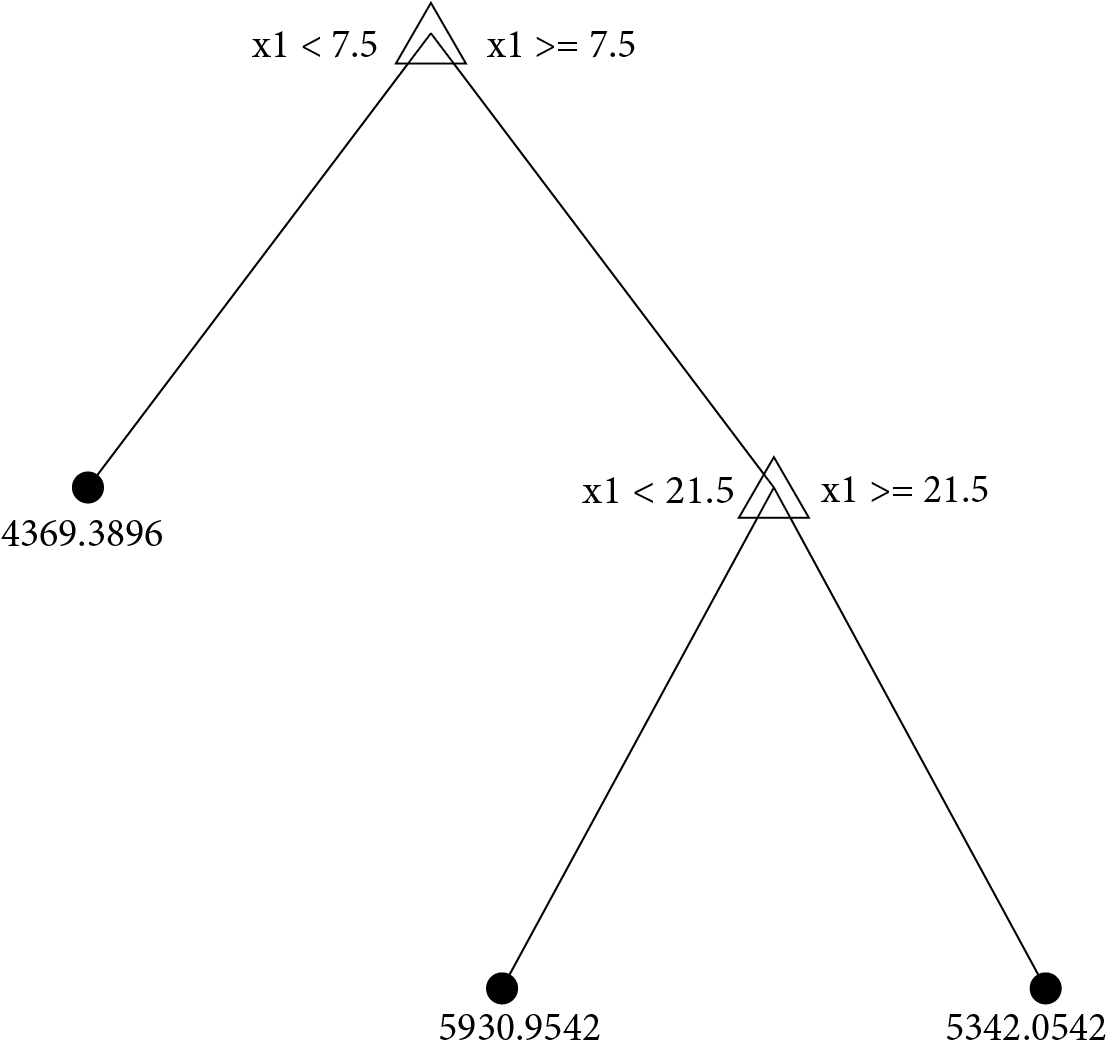

 **Reflect**

- Will the electricity load curve look different on the weekend or on a day in December?

- Are the predictions far off from the actual value? Why?

- Consider the practicality of this model for predicting future demand. For example, what is the predicted load according to this model at `x = 24`? Is this a good model for forecasting? If not, what is missing?

### **Ensemble of Trees**

A *weak learner* is an algorithm that performs just slightly better than random guessing. A good predictive model, however, is a *strong learner*. It needs to perform optimally. *Ensemble learning* is the idea that one can combine several weak learners to develop a strong learner. Shallow regression trees are commonly used as *weak learners *because a tree's "strength" can be easily controlled by controlling its depth. A collection of trees is called an ensemble of trees. There are two common ensemble techniques: *bagging* and *boosting*.

**Bagging** stands for bootstrap aggregation. It involves generating many bootstrap replicas of the data set, growing a decision tree on each replica, and aggregating the results to make a final decision. Each bootstrap replica is obtained by randomly selecting N out of N observations with replacement. This way, several observations (more than a third on average) are omitted in each replica, because of duplicated observations in the bootstrap. These are called "out-of-bag" observations.

**Boosting** refers to a family of algorithms that sequentially train the weak learners by focusing on the misclassified samples or samples with significant errors (in the case of regression) for every subsequent learner. The learners are weighted based on their performance at the time of final aggregation.

***Task:**** Click ****Fit ensemble of trees**** to view an example to model the hourly electricity load in a single day.*

load loadMayDay.mat x y
numTrees = 2;
numSplits = 1;
 

ens = showEnsembleTree(x,y,numTrees,numSplits);

  ***Try***

- *Use the slider to set the variable *`numTrees`* to increase the number of trees in the ensemble, and click the button to rerun this section.*

- *Increase the tree depth by setting the *`numSplits`* slider, and click the button to rerun this section.*

- *Try different combinations and of *`numTrees` and `numSplits`* and note your general observations.*

 **Reflect**

- Compare the fit (red line) for an ensemble of many shallow trees (`numTrees = 10`, `numSplits = 1`) with that of a single deep regression tree (`numSplits = 10`) from the previous section. What type of differences do you notice in ways that these two models fit the data? 

- Visually, which of the two models (a single deep regression tree or an ensemble of ) appears to be a better fit? Why?

## Validating and Testing

### Overfitting and Underfitting

The goal of a machine learning model is to learn from all the available observations to make accurate predictions about new observations. There are several ways to ensure that a model generalizes well to new data and does not simply *overfit* the available data. Overfitting is closely related to the notion of model complexity. A reasonably simplistic model may not capture many essential details in the data (underfitting), while a very complex model will end up learning the noise in your training data (overfitting). To achieve optimal performance, a large part of your work, as the model's architect, is to achieve the right balance through a combination of techniques and tools. In the previous sections, you might have noticed that using an ensemble of weak learners is, in fact, one way to combat overfitting. 

***Task:**** Run this section and observe the plot generated. *

[x, y] = getTrainingData;
 

% Fit a sum of sinusoids to the data.
type = fittype("sin1")     % Choose a model type to fit.
mdl = fit(x,y,type);                     % Fit the data (x,y) to the chosen model type.

% Plot the fit, along with the data samples.
figure("Position",[0 0 600 400]);
plot(x,y,"xb","MarkerSize",6)
hold on
plot(mdl,"r")
hold off

% Label the axes.
xlabel("x");
ylabel("y");
legend("Data observations","Fitted model","Location","best")

  ***Try***

- *Use the drop-down list to switch between three different models.*

 **Reflect**

- Which one of the three models overfits the training data? Which one of them underfits? Why?

### Model Evaluation

To evaluate the final performance of a trained model, it is a common practice to split the larger dataset into training and test sets. The model is NEVER exposed to the test set during its training. So, this "unseen" test data can be used to evaluate the overall performance of the model **after** it has been trained.

While there are several model-specific approaches to deal with overfitting, a general practice throughout machine learning is to further split the training set into more subsets for *validation*. One subset is used for training the model and its complementary set (called the validation set) is used for evaluating the model **during** the training. If the trained model performs far more poorly on the validation set as compared to the training set, then it is likely to be overfitted and could use further tuning of parameters. You can use the same validation data set repeatedly, or you can split a new validation set from the larger training set for each evaluation stage during the training. The first is called hold-out validation and the second is often called cross-validation. 

In part 1 of this module, you have been visually inspecting the results of fitting a regression model. However, in both the above situations—improving your model's performance during training (validation) and comparing performance across multiple models (testing), it is essential to use objective performance metrics. For regression models, this measure is often referred to as the *score*. Some examples include the Root Mean Square Error (RMSE), the Mean Square Error (MSE), and the Mean Absolute Error (MAE). 

## 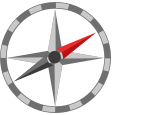Further Exploration

This module introduces a few general concepts and terminology in machine learning with a focus on regression problems. Here are some additional resources to help you dive deeper:

- Get an [overview](https://www.mathworks.com/discovery/machine-learning-models.html?source=15576&s_eid=psm_15576) of some popular models used for regression and classification.

- [Machine Learning Onramp](https://www.mathworks.com/learn/tutorials/machine-learning-onramp.html) is a free, two-hour tutorial that provides an interactive introduction to practical machine learning methods for classification problems

- [Introduction to Machine Learning (4 Videos)](https://www.mathworks.com/videos/series/introduction-to-machine-learning.html)

- [Machine Learning with MATLAB](https://www.mathworks.com/campaigns/offers/machine-learning-with-matlab.html) is an eBook that provides a step-by-step practical guide while reviewing the basics of machine learning.

In [part 2](matlab:open('./loadForecastRegression.mlx')) of this module, apply machine learning to a real-world problem by using regression techniques to forecast electricity load.

## Helper Functions

- Function to illustrate regression with one feature and one response.

function showRegression
% Generate random data for regression.
x = -3:0.1:3;
y = 2.*x-0.5+5*rand(size(x));

% Set up parameters for learning
epochs = 100;
learningRate = 0.01;

% Initialize loop
a1 = -10;                     % initial slope value
a0 = 5;                       % initial intercept value
n = length(x);                % total number of data points
r = logspace(-0.5,0,epochs);  % red color intensities for the plots

% Initialize plots
figure("Position",[0 0 800 400]);
plot(x,y,"o","MarkerSize",4,"Color","b")
hold on
fitLine = plot(xlim,a1.*xlim+a0,"-","LineWidth",1.5,"Color",[0 0 0]);
hold off
ylim([-10,10]), xlabel("x"), ylabel("y")
title("Regression","Predict continuous-valued responses")

for step=1:epochs
    % Compute gradient descent
    pause(0.02)
    yhat = a1*x + a0;
    diff = yhat - y;
    da1 = learningRate * sum(diff .* x) * 2 / n;
    da0 = learningRate * sum(diff) * 2 / n;
    a1 = a1 - da1;
    a0 = a0 - da0;
    fitLine.YData = a1*xlim+a0;
    fitLine.Color = [r(step) 0 0];
end
% Update plot with fitted line projecting into the future.
lims = xlim;
hold on
plot([lims(2),lims(2)+1.5], a1*[lims(2),lims(2)+1.5]+a0,"b--","LineWidth",1.5);
hold off
axis auto
drawnow
end

- Function to illustrate classification of data with two features into two classes.

function showClassification
% Generate random data for classification.
mu1 = [1 -2];
sigma1 = [1.2 .2; .2 1];
mu2 = [-1 1];
sigma2 = [1.15 0; 0 1.1];
x = [mvnrnd(mu1,sigma1,150); mvnrnd(mu2,sigma2,75)];
y = [zeros(150,1);ones(75,1)];
xnew = [2,2];

% Fit a discriminant model for classification.
kfoldMdls = fitcdiscr(x,y,"DiscrimType","quadratic","FillCoeffs","on","CrossVal","on");

% Initialize plots.
figure("Position",[0 0 600 400]);
plot(x(y==0,1),x(y==0,2),"ro",x(y==1,1),x(y==1,2),"b^");
T = text(xnew(1)+0.1,xnew(2)+0.1,"?","FontSize",12);
hold on
p1 = plot(xnew(1),xnew(2),"k*");
fp = fimplicit(@(x)x,"Color","black","LineWidth",1);
title("Classification","Predict discrete categories")
xlabel("x1");
ylabel("x2");
hold off

% Loop over the validation folds and update the plot of the decision boundary.
for k = 1:length(kfoldMdls.Trained)
    mdl = kfoldMdls.Trained{k};
    coeffs = mdl.Coeffs(2,1);
    C = coeffs.Const;
    L = coeffs.Linear;
    Q = coeffs.Quadratic;
    fp.Function = @(x1,x2)(C + x1.*(Q(1).*x1+Q(2).*x2) + x2.*(Q(3).*x1+Q(4).*x2) + x1.*L(1)+x2.*L(2));
    drawnow
    pause(0.5)
end

% Make a prediction for a new sample.
ynew = predict(mdl,xnew);
if ynew == 0
    color = "red";
    style = "o";
else
    color = "blue";
    style = "^";
end
set(p1,"Color",color,"Marker",style,"MarkerFaceColor",color);
T.String ="";
drawnow
end

- Function to illustrate clustering of data with two features in two groups.

function showClustering
% Generate random data for clustering.
mu1 = [1 2.5];
sigma1 = [1.2 .2; .2 1];
mu2 = [-0.5 -1.2];
sigma2 = [1.15 0; 0 1.1];
X = [mvnrnd(mu1,sigma1,150); mvnrnd(mu2,sigma2,75)];

% Initialize the cluster centers randomly.
ind = randperm(length(X));
X = X(ind,:);
C = X(1:2,:);
C0 = zeros(size(C));

% Initialize plot.
figure("Position",[0 0 600 400]);
plot(X(:,1),X(:,2),"ko","MarkerSize",4);
title("Clustering","Find groups and patterns")
xlabel("x1");
ylabel("x2");
axis equal manual
hold on
f1 = @(x,y)transpose(mvnpdf([x',y'],C(1,:),eye(2)));
h1 = fcontour(f1,'LevelList',0.03,"LineColor","r");
f2 = @(x,y)transpose(mvnpdf([x',y'],C(2,:),eye(2)));
h2 = fcontour(f2,'LevelList',0.03,"LineColor","b");

% Update the cluster centers by calculating mean distance from all data
% points.
while C ~= C0
    pause(0.5)
    dist1 = sqrt(sum((X-C(1,:)).^2,2));
    dist2 = sqrt(sum((X-C(2,:)).^2,2));

    C0 = C;
    C1 = X(dist1<dist2,:);
    C2 = X(~(dist1<dist2),:);
    C = [mean(C1);mean(C2)];

    f1 = @(x,y)transpose(mvnpdf([x',y'],C(1,:),eye(2)));
    f2 = @(x,y)transpose(mvnpdf([x',y'],C(2,:),eye(2)));
    h1.Function = f1;
    h2.Function = f2;
    drawnow
end

% Update the plot with final cluster assignments.
plot(C1(:,1),C1(:,2),"ro",C2(:,1),C2(:,2),"bo","MarkerSize",4);
drawnow
hold off
end

- Function to illustrate a regression tree with one feature and one response.

function mdl = showRegressionTree(x,y,N)
% Intialize plot.
figure("Position",[0 0 600 400]);
plot(x,y,'bo')
xlabel("x,  Hour of day (May 4^{th})");
ylabel("y,  Load (MW)");
xlim([0 23])

% Fit a regression tree model with one split.
mdl = fitrtree(x,y,"MaxNumSplits",1,"MinParentSize",2);
xnew = (min(x):0.05:max(x))';
ynew = predict(mdl,xnew);
hold on
p = plot(xnew,ynew,"LineWidth",2);
hold off
title("Regression Tree")

% Add more splits and update plot each time.
for n = 2:N
    pause(0.5)
    mdl = fitrtree(x,y,"MaxNumSplits",n,"MinParentSize",2);
    ynew = predict(mdl,xnew);
    p.XData = xnew;
    p.YData = ynew;
    drawnow
end
legend("Data observations","Fitted model","Location","best");

end

Generate data for stepwise regression model.

function [X,y] = generateData(numFeat)
% Set seed for reproduction of the four strong/relevant features to theoutput.
rng(numFeat);
strongPred = randperm(numFeat,4);      

rng("default")
X = randn(100,numFeat);                 % Generate random data containing numFeat number of features.
mu = exp(X(:,strongPred)*[0.1;.4;.2;.3] + 1);
y = poissrnd(mu);                       % The output is determined as a combination of the four features. All other features should be rejected by the model.
end

- Function to test a feature transformation with a linear regression model.

function testFeature(x,y,feature)
% Initialize plot
figure("Position",[0 0 800 400]);
tiledlayout(2,2,"TileSpacing","compact","Padding","compact");

% Plot the original data
nexttile
plot(x,y,"x","Color","b");
title("Raw data");
xlabel("x")
ylabel("y")

% Plot linear fit model to the original data
mdl = fitlm(x,y);
nexttile
plot(mdl);
xlabel("x")
ylabel("y")
title("Linear fit: y vs x")

% Plot the feature-transformed data
nexttile
plot(feature,y,"x","Color","b");
title("Feature space")
xlabel("x1")
ylabel("y")

% Plot linear fit in feature space
mdl = fitlm(feature,y);
nexttile
plot(mdl);
xlabel("x1")
ylabel("y")
title("Linear fit: y vs x1")
end

- Function illustrate an ensemble of regression trees with one feature and one response.

function ens = showEnsembleTree(x,y,numTrees,numSplits)

% Fit an ensemble of trees
t = templateTree("Type","regression","MinParentSize",2,"MaxNumSplit",numSplits);
ens = fitrensemble(x,y,"Learners",t,"NumLearningCycles",numTrees);
xnew = (min(x):0.05:max(x))';
ynew = predict(ens,xnew);

% Plot result
figure("Position",[0 0 600 400]);
plot(x,y,'ob');
hold on
plot(xnew,ynew,"r","LineWidth",2)
hold off
xlabel("x,  Hour of day (May 4^{th})");
ylabel("y,  Load (MW)");
end

- Function to generate data to fit models of varying complexities.

function [x,y] = getTrainingData()
rng(12)
x = linspace(0,1,50)';
y = 2*sin(0.5*pi*x)-3*sin(4*pi*x)+0.5*sin(2*pi*x)-10*sin(pi*x)+3*rand(size(x));
end